% Grey reproduction fine tuning
% by Alessandro Beltrami, November 2021

%---- STEP 1  

% Read the measurement file
fmeas = fopen('Indigo_26Nov_8R_Grey_M1.txt');
meas=[];
i=1;
line = '';
while strcmp(line,'BEGIN_DATA')==0
    line=strtrim(fgetl(fmeas));
end
while strcmp(line,'END_DATA')==0
    line=strtrim(fgetl(fmeas));
    if strcmp(line,'END_DATA')
        break;
    end
    values=textscan(line,'%d %f %f %f %f %f %f %f');
    meas(i,:)=[values{2:8}]; % C, M, Y, K, L, a, b
    i=i+1;
end
fclose(fmeas);

% Read the grey axes definition
T = readtable('FOGRA51_GreyAxis.txt',"FileType","text");
greyscale=[15; 30; 50; 70; 85];
n=size(greyscale,1);
greyaxis=zeros(n,8);
for i=1:n
    greyaxis(i,:)=T(T.SAMPLE_NAME==greyscale(i),:).Variables;
end
greyaxis % TV, C, M, Y, K, L, a, b

greyaxis =    15.0000   11.7647    8.6275    8.2353         0   85.9300    1.3300   -5.6600
   30.0000   23.9216   17.6471   17.2549         0   76.6200    1.0900   -4.8500
   50.0000   41.5686   32.5490   31.7647         0   62.8700    1.0000   -3.8900
   70.0000   62.3529   52.9412   51.3725         0   46.9200    0.8100   -2.8600
   85.0000   81.5686   76.0784   74.1176         0   32.2900    0.8700   -2.1900


-------------------------------------
Find keypoint chart K 15


ctable = 49×8 table
    CMYK_C    CMYK_M    CMYK_Y    CMYK_K    LAB_L    LAB_A    LAB_B    DELTA 
    ______    ______    ______    ______    _____    _____    _____    ______

    11.76      6.27      5.88       0        86.5    1.33     -7.76       2.1
    11.76      7.06      5.88       0       85.95     1.8     -8.36    2.7406
    11.76      7.84      5.88       0       85.58    2.51     -8.63    3.1958
    11.76      8.63      5.88       0       84.97    3.19     -8.73    3.5895
    11.76      9.41      5.88       0       84.55    3.82     -8.79    3.9996
    11.76      10.2      5.88       0       84.18    4.71     -9.01    4.7589
    11.76     10.98      5.88       0       83.74    5.64     -9.19    5.5711
    1

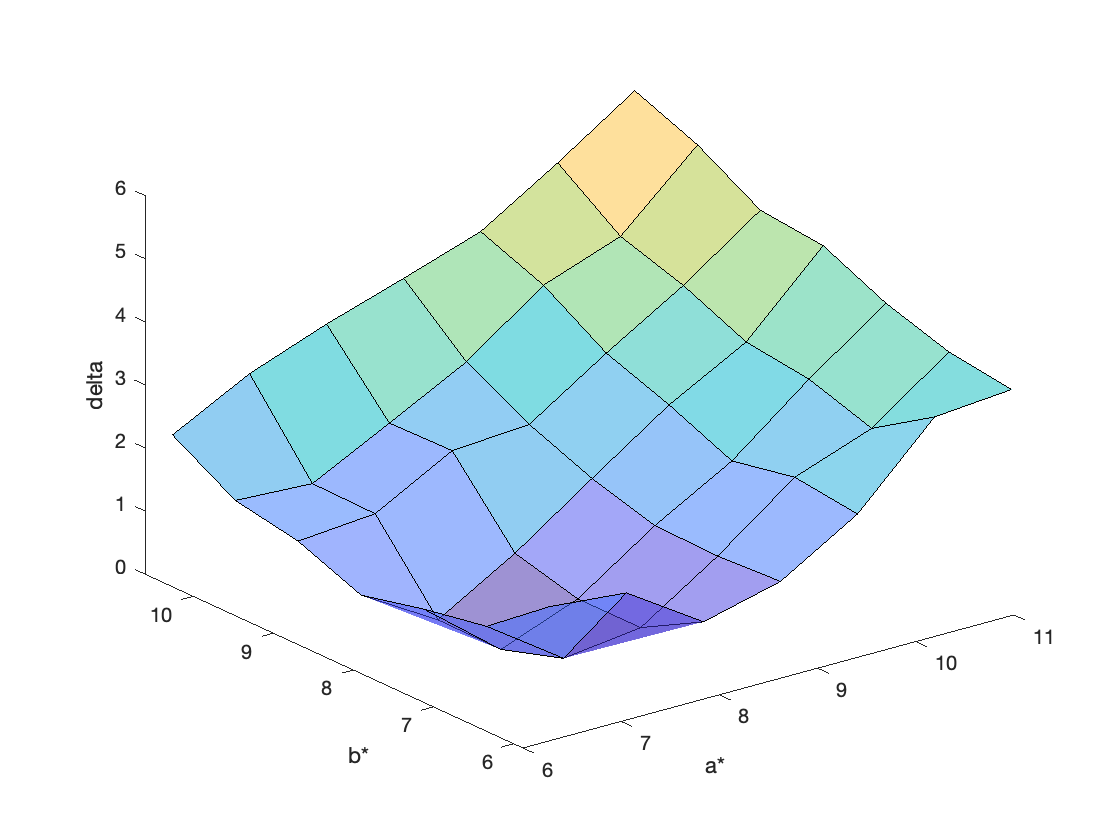

C=11.76 M=7.06 Y=9.02 delta=0.20



-------------------------------------
Find keypoint chart K 30


ctable = 169×8 table
    CMYK_C    CMYK_M    CMYK_Y    CMYK_K    LAB_L    LAB_A    LAB_B     DELTA 
    ______    ______    ______    ______    _____    _____    ______    ______

    23.92     12.94     12.55       0       76.84    0.19      -9.19    4.4323
    23.92     13.73     12.55       0        76.1    0.83      -9.73    4.8869
    23.92     14.51     12.55       0       75.62    1.28      -9.23    4.3841
    23.92     15.29     12.55       0       75.51    1.64      -9.77    4.9506
    23.92     16.08     12.55       0       74.91    2.37      -10.1    5.4038
    23.92     16.86     12.55       0       74.78    2.47     -10.06    5.3897
    23.92     17.65     12.55       0       74.28    2.73     -10.03    5.

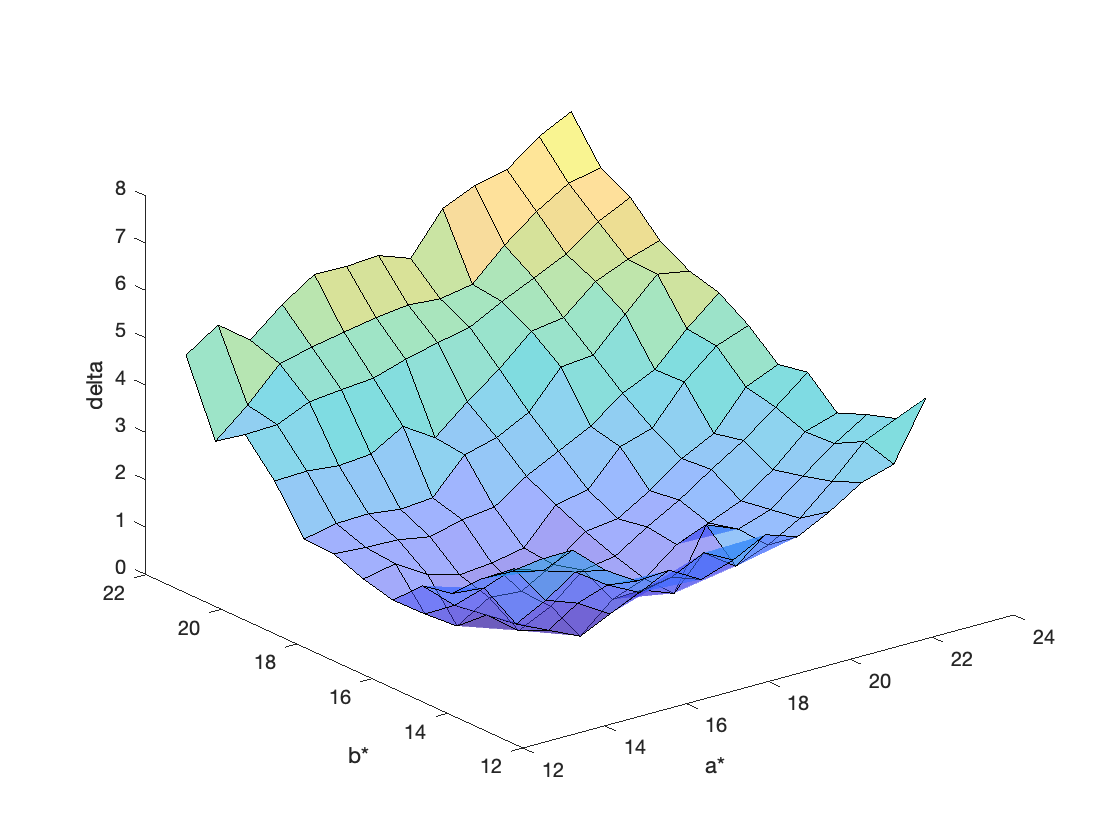

C=23.92 M=16.08 Y=19.61 delta=0.34



-------------------------------------
Find keypoint chart K 50


ctable = 169×8 table
    CMYK_C    CMYK_M    CMYK_Y    CMYK_K    LAB_L    LAB_A    LAB_B    DELTA 
    ______    ______    ______    ______    _____    _____    _____    ______

    41.57     27.84     27.06       0       66.36    -0.81    -7.09    3.6764
    41.57     28.63     27.06       0       65.77    -0.12    -7.65    3.9233
    41.57     29.41     27.06       0       65.59     0.58    -7.91    4.0419
    41.57      30.2     27.06       0       65.15     0.56    -7.72    3.8552
    41.57     30.98     27.06       0       65.05     1.26    -7.81    3.9286
    41.57     31.76     27.06       0       64.75     1.54    -7.62    3.7689
    41.57     32.55     27.06       0       64.26     2.02    -7.75    3.9925
    

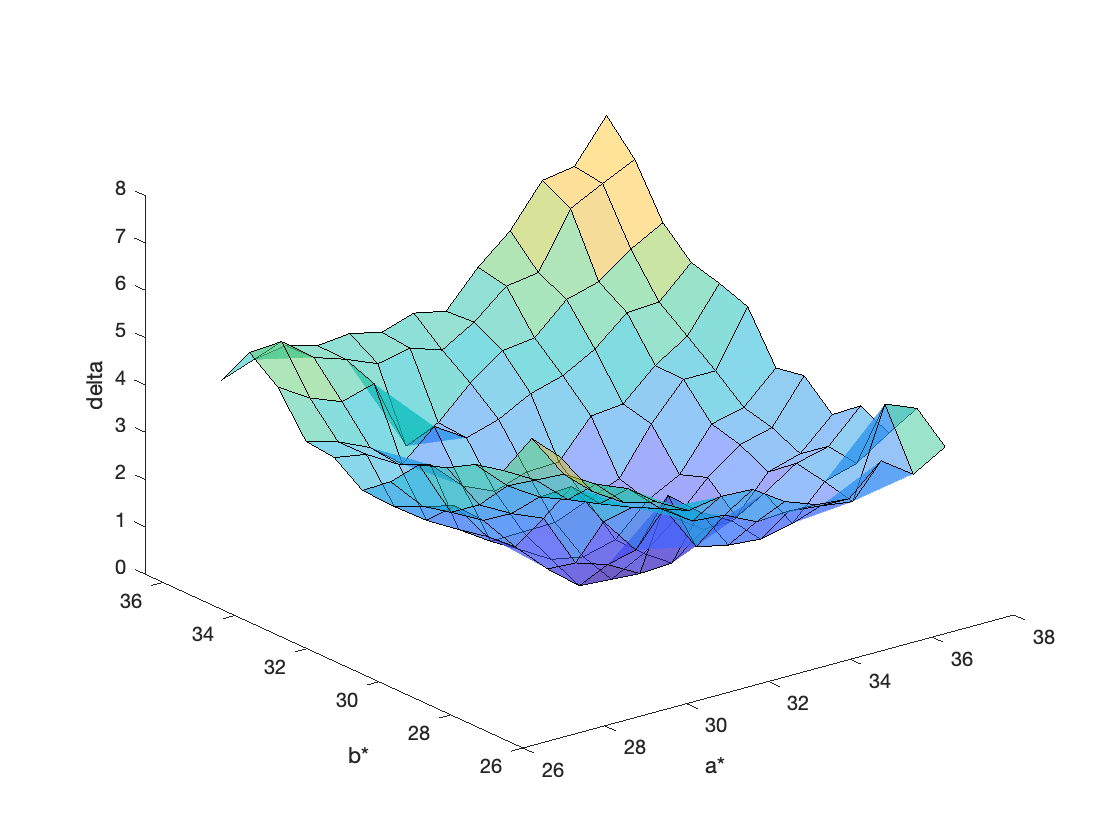

C=41.57 M=32.55 Y=32.55 delta=0.29



-------------------------------------
Find keypoint chart K 70


ctable = 169×8 table
    CMYK_C    CMYK_M    CMYK_Y    CMYK_K    LAB_L    LAB_A    LAB_B    DELTA 
    ______    ______    ______    ______    _____    _____    _____    ______

    62.35     48.24     46.67       0       49.02    -3.61    -5.78    5.2974
    62.35     49.02     46.67       0       49.42    -2.13    -6.28      4.51
    62.35      49.8     46.67       0       48.91    -2.09    -6.18    4.4082
    62.35     50.59     46.67       0       48.48     -0.9    -6.27    3.8147
    62.35     51.37     46.67       0       47.82    -0.29    -6.36    3.6688
    62.35     52.16     46.67       0       47.56     0.53    -6.26    3.4115
    62.35     52.94     46.67       0       46.92     1.41    -6.94    4.1239
    

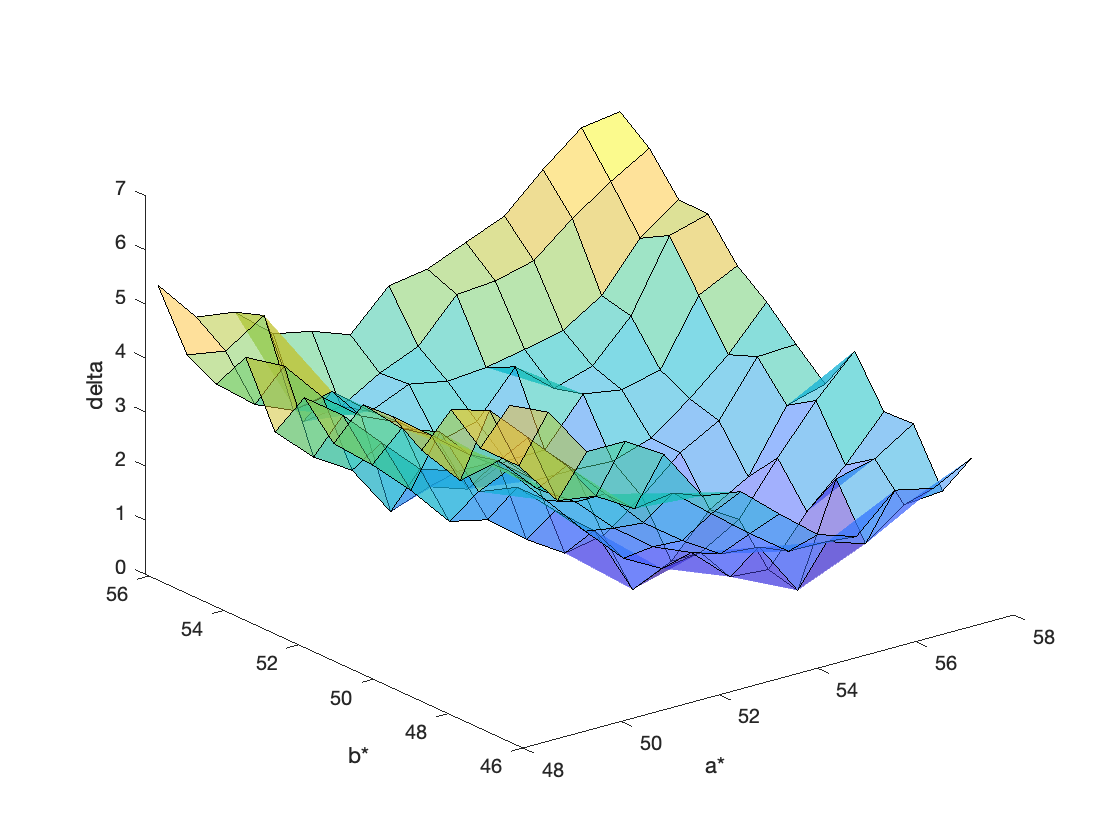

C=62.35 M=53.73 Y=52.16 delta=0.06



-------------------------------------
Find keypoint chart K 85


ctable = 49×8 table
    CMYK_C    CMYK_M    CMYK_Y    CMYK_K    LAB_L    LAB_A    LAB_B     DELTA 
    ______    ______    ______    ______    _____    _____    _____    _______

    81.57     73.73     71.76       0       32.53    -1.29    -3.35     2.4518
    81.57     74.51     71.76       0       32.47     -1.1    -4.52     3.0512
    81.57     75.29     71.76       0       33.58    -0.17    -3.75     1.8749
    81.57     76.08     71.76       0       33.29     1.07    -3.94     1.7614
    81.57     76.86     71.76       0       32.69      1.8    -4.36     2.3609
    81.57     77.65     71.76       0       32.35     2.63    -4.91     3.2398
    81.57     78.43     71.76       0       32.06     3.24    -5.32      3.

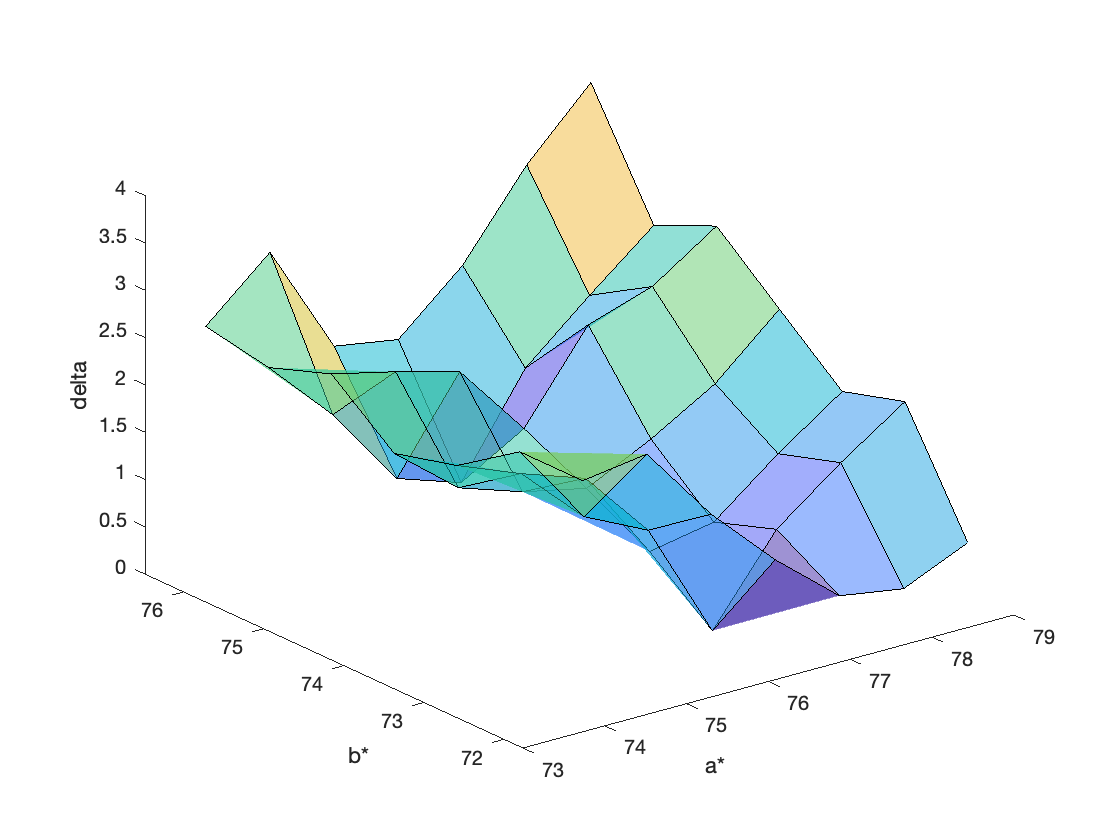

C=81.57 M=76.08 Y=75.69 delta=0.21



% Join the measurements and the reference Lab values from grey axis
newM=zeros(n,1);
newY=zeros(n,1);
delta=zeros(n,1);
for i = 1:n
    % get the measurements that have the same value of C (chart)
    chart = meas(abs(meas(:,1)-greyaxis(i,2))<1,:);
    % add the DeltaC column to the chart
    chart(:,8) = sqrt(power(chart(:,6)-greyaxis(i,7),2)+power(chart(:,7)-greyaxis(i,8),2));
    % find the minimum delta and plot the graphs
    fprintf('-------------------------------------\nFind keypoint chart K %d\n',greyaxis(i,1));
    ctable = table(chart(:,1),chart(:,2),chart(:,3),chart(:,4),chart(:,5),chart(:,6),chart(:,7),chart(:,8),...
        'VariableNames',{'CMYK_C','CMYK_M','CMYK_Y','CMYK_K','LAB_L','LAB_A','LAB_B','DELTA'})    
    
    [newM(i), newY(i), delta(i)]=findMinimums(ctable);
    
    fprintf('C=%.2f M=%.2f Y=%.2f delta=%.2f\n\n',ctable.CMYK_C(1),newM(i),newY(i),delta(i))
end

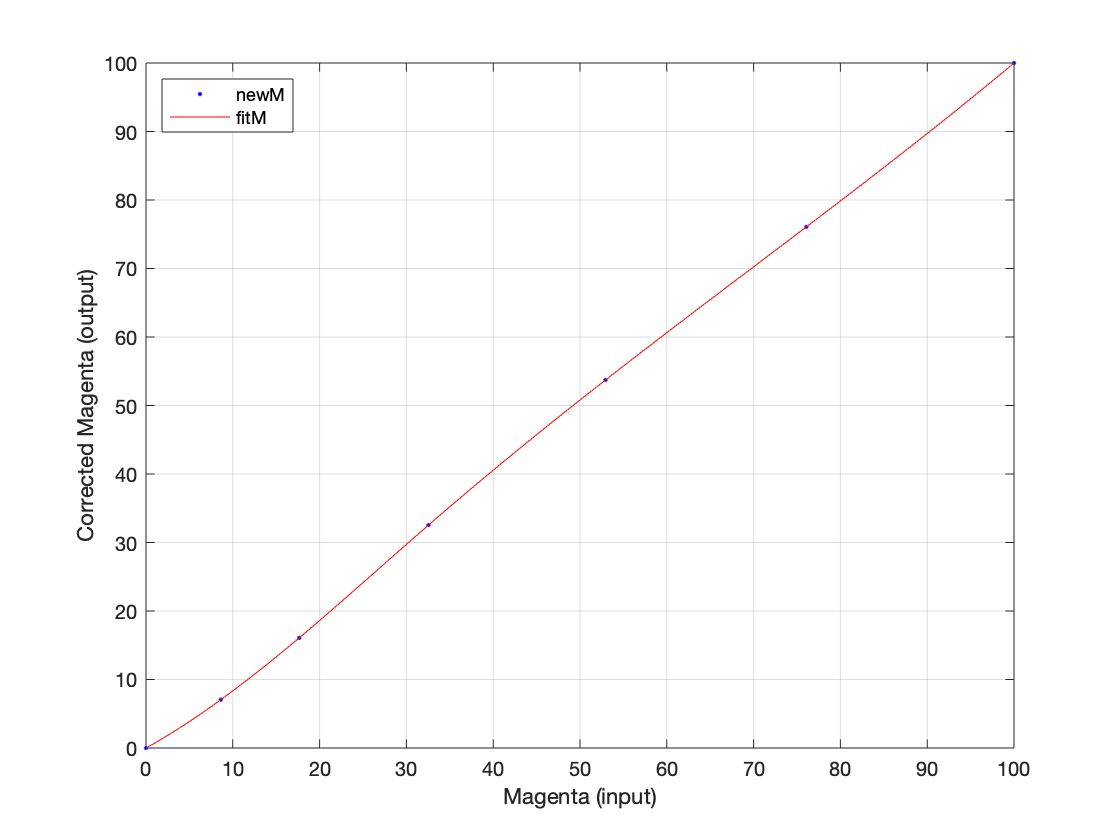

%---- STEP 2  

% interpolate M curve, adding 0 and 100 anchor extreme points
xM= [0; greyaxis(:,3); 100];
yM= [0; newM; 100];
[xData, yData] = prepareCurveData(xM,yM);
[fitM, ] = fit(xData,yData,'splineinterp'); %spline interpolation
figure;
h = plot( fitM, xData, yData );
legend( h, 'newM', 'fitM', 'Location', 'NorthWest', 'Interpreter', 'none' );
xlabel( 'Magenta (input)', 'Interpreter', 'none' );
ylabel( 'Corrected Magenta (output)', 'Interpreter', 'none' );
xlim([0 100]);
ylim([0 100]);
grid on

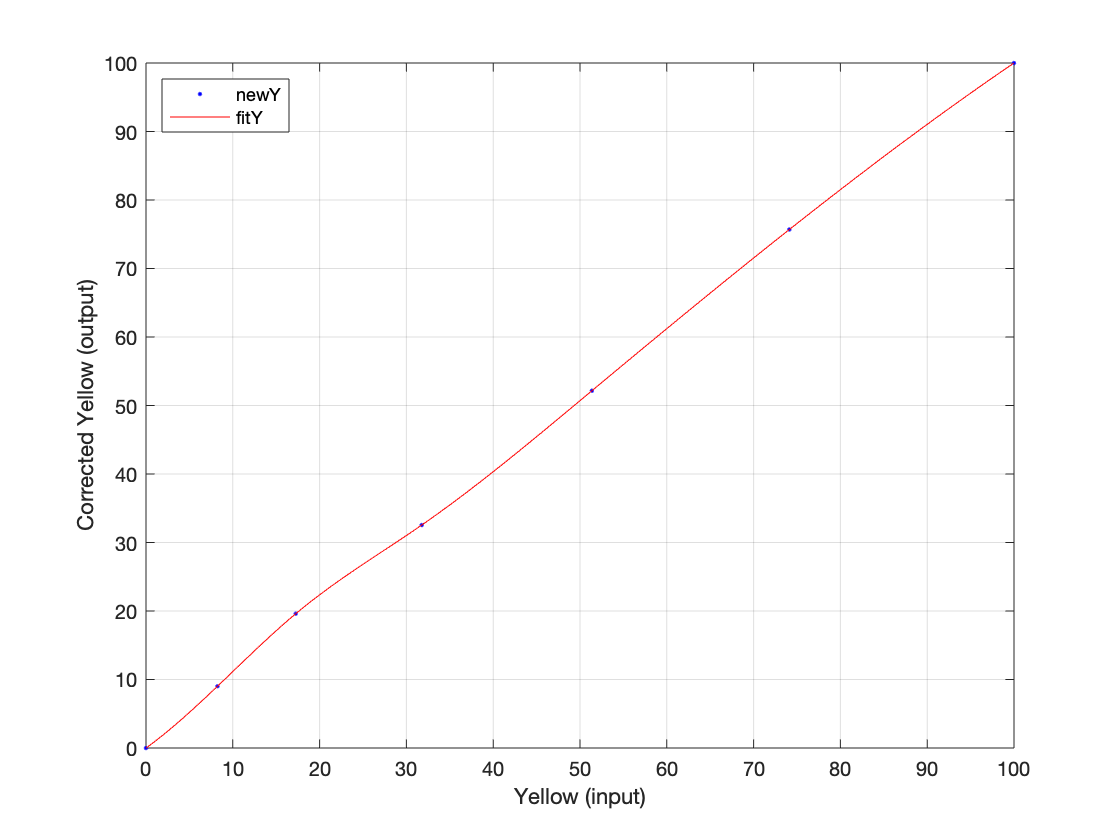

% interpolate Y curve, adding 0 and 100 anchor extreme points
xY= [0; greyaxis(:,4); 100];
yY= [0; newY; 100];
[xData, yData] = prepareCurveData(xY,yY);
[fitY, ] = fit(xData,yData,'splineinterp'); %spline interpolation
figure;
h = plot( fitY, xData, yData );
legend( h, 'newY', 'fitY', 'Location', 'NorthWest', 'Interpreter', 'none' );
xlabel( 'Yellow (input)', 'Interpreter', 'none' );
ylabel( 'Corrected Yellow (output)', 'Interpreter', 'none' );
xlim([0 100]);
ylim([0 100]);
grid on

%---- STEP 3  


% Load current LUT
lut = readtable('Current LUT.xlsx');
TV=table2array(lut(:,'TV')); % tone value entry
LutM=table2array(lut(:,'LUT_M')); % current M
LutY=table2array(lut(:,'LUT_Y')); % current Y

% Interpolate M current LUT
[xTV, yLutM] = prepareCurveData(TV,LutM);
[fitLutM, ] = fit(xTV,yLutM,'splineinterp');
% Interpolate Y current LUT
[xTV, yLutY] = prepareCurveData(TV,LutY);
[fitLutY, ] = fit(xTV,yLutY,'splineinterp');

% Calculate newLUT=LUT(correction(TV))
newM=fitLutM(fitM(TV));
newY=fitLutY(fitY(TV));
% Adding columns to the current LUT
newlut=addvars(lut,newM,newY,'NewVariableNames',{'NEW_LUT_M','NEW_LUT_Y'});
% Write the calibrated LUT table
writetable(newlut,'Calibrated LUT.xlsx',"FileType","spreadsheet");
newlut

newlut = 21×7 table
    TV    LUT_C     LUT_M     LUT_Y     LUT_K     NEW_LUT_M    NEW_LUT_Y
    __    ______    ______    ______    ______    _________    _________

     0         0         0         0         0          0            0  
     5     9.214    8.9469    7.8531    10.503     6.9594       8.1862  
    10     17.67    17.394    16.214    19.593     14.652       18.155  
    15    25.469    25.314     24.44    27.561     22.684       27.809  
    20    32.698    32.714    32.218    34.647     30.717       35.699  
    25     39.43    39.622    39.424    41.041     38.472       41.904  
    30    45.727    46.076     46.04    46.893     45.738       47.328  
    35     51.64    52.115    52.102    52.322     52.375       52.664  
    40    5

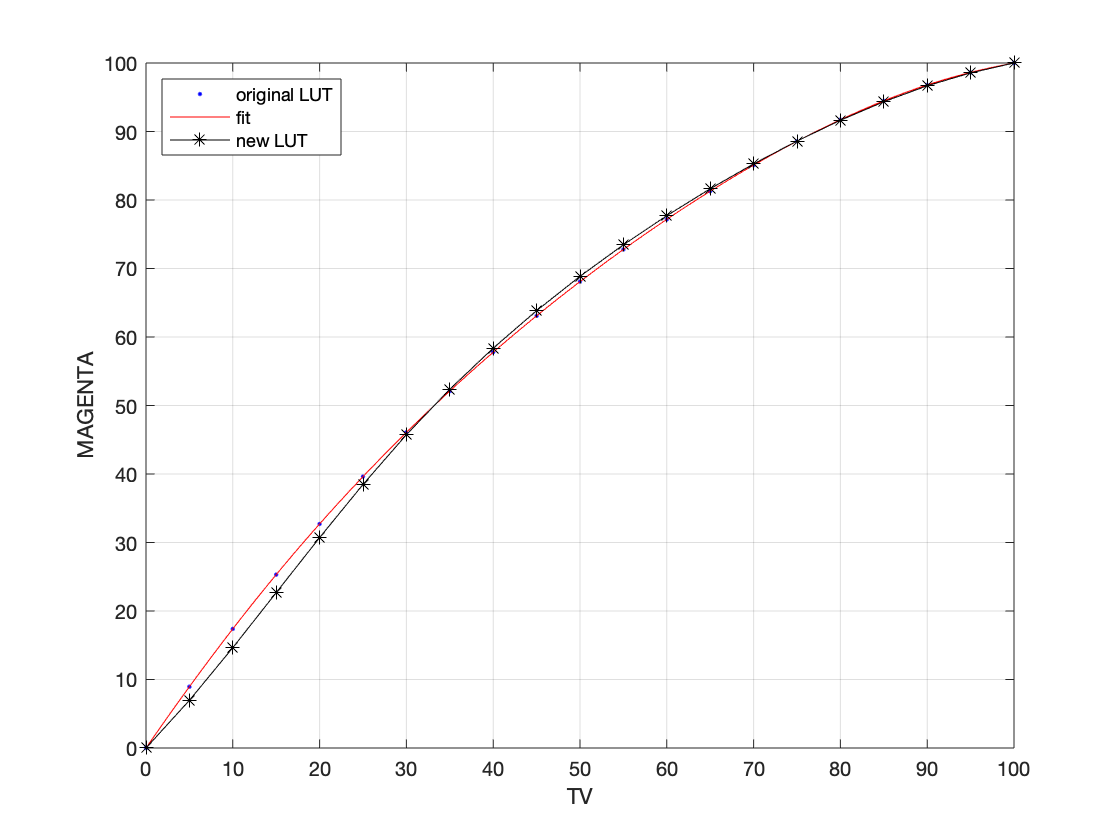

% Plot the current and corrected LUTs

figure; 
plot( fitLutM, xTV, yLutM);
hold on;
plot(xTV,newM,'k*-');
legend( 'original LUT', 'fit', 'new LUT', 'Location', 'NorthWest', 'Interpreter', 'none' );
xlabel( 'TV', 'Interpreter', 'none' );
ylabel( 'MAGENTA', 'Interpreter', 'none' );
xlim([0 100]);
ylim([0 100]);
grid on

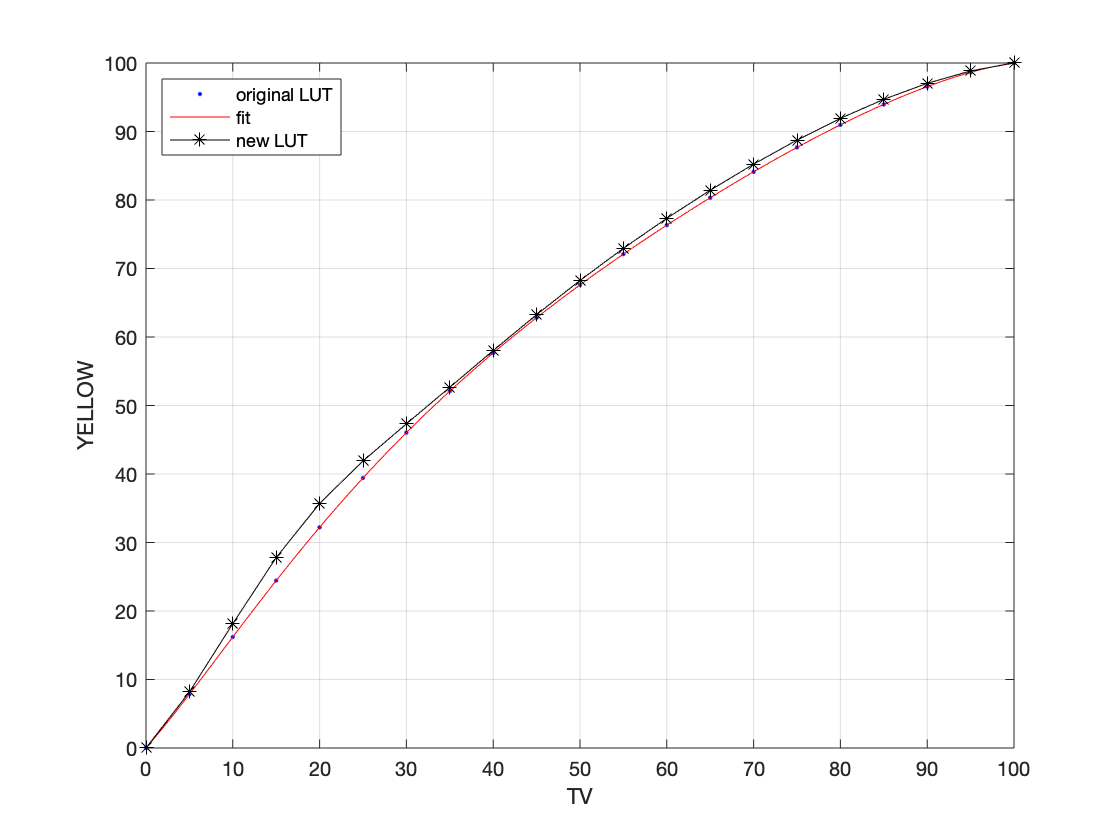

figure; 
plot( fitLutY, xTV, yLutY);
hold on;
plot(xTV,newY,'k*-');
legend( 'original LUT', 'fit', 'new LUT', 'Location', 'NorthWest', 'Interpreter', 'none' );
xlabel( 'TV', 'Interpreter', 'none' );
ylabel( 'YELLOW', 'Interpreter', 'none' );
xlim([0 100]);
ylim([0 100]);
grid on